# **BMTS - BCE AC Signal Modulation**

This example shows you how to use the AC Signal Modulation functionality of the Speedgoat Battery Cell Emulator (BCE) unit to output predefined signals at higher frequencies than the model's base sample rate.

High-frequency signal modulation can be used to enable more comprehensive BMS analysis, such as electrochemical impedance spectroscopy (EIS) and electromagnetic noise and disturbance testing.

Note that the BCE SoC firmware must be updated to version 1.1.0.0 or later to enable the AC Signal Modulation feature (refer to [BMTS Firmware Update Instructions](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bmts_update_instructions)).

The Simulink model features the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup), [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read), [BMTS Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_write), and [BMTS Bus Pack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bmts_buspack) blocks.

## Setup

### Prerequisites

You will require the following to execute this example:

- Speedgoat real-time target machine with a free Ethernet port

- Speedgoat Battery Cell Emulator

- Ethernet cable from the target machine to the BCE

### Test Setup

In this example, a BCE12-0605 with a voltage rating of 6 V is used. No external connection between the cells is required. Each cell reads back the voltage it generates.

### Configuration

The Speedgoat real-time target machine communicates with the Speedgoat Battery Cell Emulator via EtherCAT. For this purpose, the Ethernet port of the target machine must be configured for EtherCAT.

Use a CAT5 cable or newer to connect the target machine and the BCE. On the target machine, choose an unused RJ45 Ethernet connector, an onboard interface, or an IO71x/IO791 I/O module. Plug the other end of the cable into the upper RJ45 connector of the BCE, labeled "ETH1".

To activate EtherCAT support for the respective interface, enter the following in the MATLAB command window to open the Ethernet Configuration Tool:

Select **EtherCAT** in the **Configuration** column for the chosen interface, as shown below for the ETH1 interface:

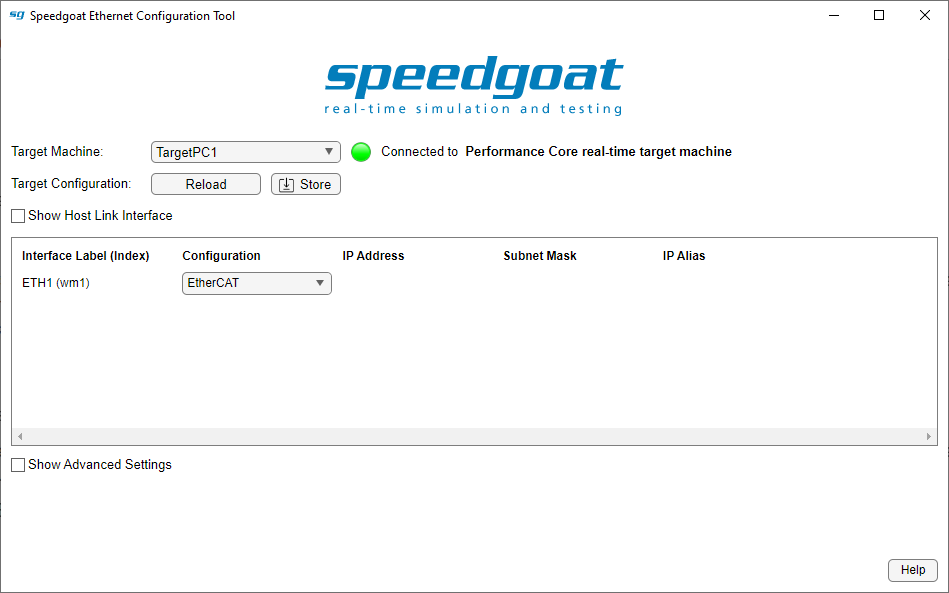

Click the **Store** button to store the configuration on the target machine and then close the Ethernet Configuration Tool when the process has finished.

## Open Simulink Model

 
modelName = 'sgMdl_BMTS_BCEACSignalModulation';
open_system(modelName);         % Open Simulink model

## Create AC Signal Data File

The file ACSignalData.mat is created using the following code:

 
tmr = linspace(0,2*pi,200);        % Generate 200 linearly spaced samples in (0,2*pi)
samples = 0.5*sin(tmr);            % Sample sine wave with amplitude 0.5
data = repmat(samples', 1, 12);    % Copy samples into an array with 12 columns (1 for each cell)
save('ACSignalData.mat', 'data');  % Save file
clear tmr samples data;            % Clean up variables

## Build, Download, and Run the Example

To execute the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Open the Simulation Data Inspector
Simulink.sdi.view;

% Start the real-time application
tg.setStopTime(20);
tg.start;

% Wait for the application to stop
while(strcmp(tg.status, 'running'))
    pause(1);
end

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('V_Cell1'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [1 0.4118 0.1608];
s = sdiLatestRun.getSignalsByName('V_Cell2'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.0745 0.6235 1];
Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,20,-0.3,4]);

### Check the Results

Open the Simulink scope connected to the [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read) block and compare the signals to check if the voltage modulation is working as expected. On the analog scope, the voltage of cells 1 and 2 are displayed. The voltage of cell 1 ramps up to a base value of 3 V between 4 s and 5 s of simulation time, while the voltage of cell 2 is ramped up to a base value of 2 V.

At t = 6 s, the AC_Modulation_Start signal for cells 1 and 2 is enabled. The cells start synchronously outputting the data defined in ACSignalData.mat at the rate of 1 ms, as configured in the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup) block tab "BCE AC Signal Modulation".

The time step of 1 ms is chosen such that the signal can be read and displayed fully at the model base sample rate of 1 ms. Nevertheless, the time step between AC signal updates can be set as low as 7 μs.

The array in ACSignalData.mat consists of 200 samples of a single sine wave period with amplitude 0.5. A 100 ms start time delay is added to the AC signal of cell 2 to showcase the synchronized output. The output path for the AC signal is set to "Voltage". While the AC Signal Modulation is active, the selected output path is solely under AC Signal Modulation control. The non-selected output path behaves normally and remains under user control.

Note that for both cells 1 and 2, a sink current of 0.5 A is set. Without any external wiring, this current is supplied internally by each cell, which allows the voltage to drop fast enough to read back a clean sine wave in the cell voltage measurement.

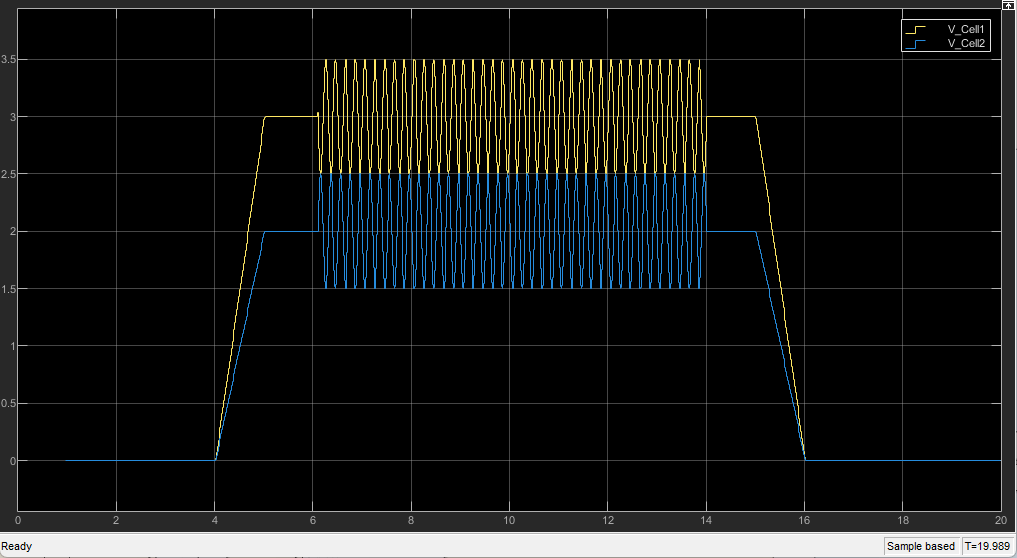

## Additional References

- [BCE Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_usage_notes)

- [BMTS Firmware Update Instructions](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bmts_update_instructions)